% Creates the parallel pool
parpool;

Starting parallel pool (parpool) using the 'Processes' profile ...
Parallel pool using the 'Processes' profile is shutting down.



## **SNR = 1, PAM, N = 2, Loop, a^b, No paralellization**

clc; clear;

% Values of M
Array_M = [2 4 8 16 32 64 128 256 512 1024];

% Quadrature nodes and weights
N = 2;
[nodes, weights] = GaussHermite_Locations_Weights(N);

% Signal-to-Noise Ratio
SNR = 1;

% Gaussian expression
G = @(z) (1/pi) * exp(-abs(z).^2);

%rho = 0.5
rho_values = 0.5;

% Initialize array to store computation times
computation_times = zeros(size(Array_M));

% Loop over different constellation sizes
for i = 1:length(Array_M)
    M = Array_M(i);
    d = 2;

    % Generate constellation
    X = generatePAMConstellation(M, d);

    % Normalize constellation to have unit energy
    avg_energy = mean(X.^2);
    X = X / sqrt(avg_energy);

    % Equal probabilities
    Q = ones(1, M) / M;

    Eo_rho = zeros(size(rho_values));

    % Start the timer
    tic;

    % Loop over rho values to calculate E0(rho)
    for j = 1:length(rho_values)
        rho = rho_values(j);  % Set current rho value
        integral_sum = 0;  % Initialize integral sum for the current rho

        % Loop over PAM symbols (using indices)
        for x_idx = 1:length(X)
            x = X(x_idx);  % Get the current symbol value
            quadrature_sum = 0;  % Initialize quadrature sum for the current symbol

            % Nested loop over quadrature nodes
            for k = 1:N
                for l = 1:N
                    z = nodes(k) + 1i * nodes(l);  % Combine nodes into complex value z
                    fp_sum = 0;
                    for x_bar_idx = 1:length(X)
                        x_bar = X(x_bar_idx);  % Get the current x_bar value
                        fp_sum = fp_sum + (Q(x_idx) * (G(z + sqrt(SNR)*x - sqrt(SNR)*x_bar)^(1/(1+rho))));
                    end
                    fp = fp_sum / (G(z)^(1/(1+rho)));
                    quadrature_sum = quadrature_sum + weights(k) * weights(l) * (fp^rho);
                end
            end
            % Accumulate the integral sum for the current symbol
            integral_sum = integral_sum + Q(x_idx) * quadrature_sum;
        end

        % Calculate E0(rho) for the current rho value
        Eo_rho(j) = -log2((1/pi) * integral_sum);
    end

    % Record computation time
    computation_times(i) = round(toc * 1000); % Convert seconds to milliseconds

    % Display computation time for current constellation size
    disp(['Computation time for M = ', num2str(M), ': ', num2str(computation_times(i)), ' milliseconds']);
end

% Plot computation time vs. constellation size
figure;
plot(Array_M, computation_times);
xlabel('Constellation Size (M)');
ylabel('Computation Time (milliseconds)');
title('Computation Time vs. Constellation Size');

% Display summary of computation times and Eo_rho values
disp('Computation Times for Different Constellation Sizes:');
disp(table(Array_M', computation_times', 'VariableNames', {'Constellation Size (M)', 'Computation Time (milliseconds)'}));

## SNR = 1, PAM, N = 2, Loop, e^b*ln(a), No paralellization

clc; clear;

% Define constellation sizes to test
Array_M = [2 4 8 16 32 64 128 256 512 1024];

% Initialize array to store computation times and Eo_rho values
computation_times = zeros(size(Array_M));
Eo_final_values = zeros(size(Array_M));

% Quadrature nodes and weights
N = 2;
[nodes, weights] = GaussHermite_Locations_Weights(N);

SNR = 1;

%rho = 0.5
rho_values = 0.5;

G = @(z) (1/pi) * exp(-abs(z).^2); % Exponential replaced below

% Loop over different constellation sizes
for i = 1:length(Array_M)
    M = Array_M(i);
    d = 2;

    % Generate constellation
    X = generatePAMConstellation(M, d);

    % Normalize constellation to have unit energy
    avg_energy = mean(X.^2);
    X = X / sqrt(avg_energy);

    % Equal probabilities
    Q = ones(1, M) / M;
    
    % Initialize E0(rho) values
    Eo_rho = zeros(size(rho_values));

    % Start the timer
    tic;

    % Loop over rho values to calculate E0(rho)
    for j = 1:length(rho_values)
        rho = rho_values(j);  % Set current rho value
        integral_sum = 0;  % Initialize integral sum for the current rho

        % Loop over PAM symbols (using indices)
        for x_idx = 1:length(X)
            x = X(x_idx);  % Get the current symbol value
            quadrature_sum = 0;  % Initialize quadrature sum for the current symbol

            % Nested loop over quadrature nodes
            for k = 1:N
                for l = 1:N
                    z = nodes(k) + 1i * nodes(l);  % Combine nodes into complex value z
                    fp_sum = 0;
                    for x_bar_idx = 1:length(X)
                        x_bar = X(x_bar_idx);  % Get the current x_bar value
                        % Replace exponential with e^(b * ln(a))
                        term1 = log(G(z + sqrt(SNR)*x - sqrt(SNR)*x_bar));
                        fp_sum = fp_sum + (Q(x_idx) * exp((1/(1+rho)) * term1));
                    end
                    % Replace exponential with e^(b * ln(a))
                    term2 = log(G(z));
                    fp = fp_sum / exp((1/(1+rho)) * term2);
                    % Replace exponential with e^(b * ln(a))
                    term3 = log(fp);
                    quadrature_sum = quadrature_sum + weights(k) * weights(l) * exp(rho * term3);
                end
            end
            % Accumulate the integral sum for the current symbol
            integral_sum = integral_sum + Q(x_idx) * quadrature_sum;
        end

        % Calculate E0(rho) for the current rho value
        % Replace exponential with e^(b * ln(a))
        term4 = log((1/pi) * integral_sum);
        Eo_rho(j) = -log2(exp(term4));
    end

    % Record computation time
    computation_times(i) = round(toc * 1000); % Convert seconds to milliseconds

    % Display computation time for current constellation size
    disp(['Computation time for M = ', num2str(M), ': ', num2str(computation_times(i)), ' milliseconds']);
end

% Plot computation time vs. constellation size
figure;
plot(Array_M, computation_times);
xlabel('Constellation Size (M)');
ylabel('Computation Time (milliseconds)');
title('Computation Time vs. Constellation Size');

% Display summary of computation times and Eo_rho values
disp('Computation Times for Different Constellation Sizes:');
disp(table(Array_M', computation_times', 'VariableNames', {'Constellation Size (M)', 'Computation Time (milliseconds)'}));

## SNR = 1, PAM, N = 2, Loop, a^b, MATLAB default parallelization

clc; clear;

% Define constellation size
M = 1028; 
d = 2;

% Generate constellation
X = generatePAMConstellation(M, d);

% Normalize constellation to have unit energy
avg_energy = mean(X.^2);
X = X / sqrt(avg_energy);

% Equal probabilities
Q = ones(1, M) / M;

% Quadrature nodes and weights
N = 2; 
[nodes, weights] = GaussHermite_Locations_Weights(N); 

SNR = 1;

G = @(z) (1/pi) * exp(-abs(z).^2);

%rho = 0.5
rho_values = 0.5;

% Initialize E0(rho) values
Eo_rho = zeros(size(rho_values));

% Start the timer
tic;

% Parallelize the computation of Eo_rho
for j = 1:length(rho_values)
    rho = rho_values(j);  % Set current rho value
    integral_sum = 0;  % Initialize integral sum for the current rho

    % Loop over PAM symbols (using indices)
    for x_idx = 1:length(X)
        x = X(x_idx);  % Get the current symbol value
        quadrature_sum = 0;  % Initialize quadrature sum for the current symbol

        % Nested loop over quadrature nodes
        for k = 1:N
            for l = 1:N
                z = nodes(k) + 1i * nodes(l);  % Combine nodes into complex value z
                fp_sum = 0;
                for x_bar_idx = 1:length(X)
                    x_bar = X(x_bar_idx);  % Get the current x_bar value
                    fp_sum = fp_sum + (Q(x_idx) * (G(z + sqrt(SNR)*x - sqrt(SNR)*x_bar)^(1/(1+rho)))); 
                end
                fp = fp_sum / (G(z)^(1/(1+rho)));
                quadrature_sum = quadrature_sum + weights(k) * weights(l) * (fp^rho);
            end
        end
        % Accumulate the integral sum for the current symbol
        integral_sum = integral_sum + Q(x_idx) * quadrature_sum;
    end

    % Calculate E0(rho) for the current rho value
    Eo_rho(j) = -log2((1/pi) * integral_sum);
end

computation_time = round(toc * 1000); % Convert seconds to milliseconds

disp(['Computation time for M = ', num2str(M), ': ', num2str(computation_time), ' milliseconds']);

## SNR = 1, PAM, N = 2, Loop, e^b*ln(a), MATLAB default parallelization

clc; clear;

% Define constellation size
M = 512; 
d = 2;

% Generate constellation
X = generatePAMConstellation(M, d);

% Normalize constellation to have unit energy
avg_energy = mean(X.^2);
X = X / sqrt(avg_energy);

% Equal probabilities
Q = ones(1, M) / M;

% Quadrature nodes and weights
N = 2;
[nodes, weights] = GaussHermite_Locations_Weights(N);

SNR = 1;

G = @(z) (1/pi) * exp(-abs(z).^2); 

% Rho values to evaluate, ranging from 0 to 1
rho_values = 0.5;

% Initialize E0(rho) values
Eo_rho = zeros(size(rho_values));

% Start the timer
tic;

% Parallelize the loop over rho values using parfor
parfor j = 1:length(rho_values)
    rho = rho_values(j);  % Set current rho value
    integral_sum = 0;  % Initialize integral sum for the current rho

    % Loop over PAM symbols (using indices)
    for x_idx = 1:length(X) 
        x = X(x_idx);  % Get the current symbol value
        quadrature_sum = 0;  % Initialize quadrature sum for the current symbol

        % Nested loop over quadrature nodes
        for k = 1:N
            for l = 1:N
                z = nodes(k) + 1i * nodes(l);  % Combine nodes into complex value z
                fp_sum = 0;
                for x_bar_idx = 1:length(X)
                    x_bar = X(x_bar_idx);  % Get the current x_bar value
                    % Apply the exponential transformation
                    fp_sum = fp_sum + (Q(x_idx) * (exp((1/(1+rho)) * log(G(z + sqrt(SNR)*x - sqrt(SNR)*x_bar))))); 
                end
                fp = fp_sum / exp((1/(1+rho)) * log(G(z)));
                quadrature_sum = quadrature_sum + weights(k) * weights(l) * exp(rho * log(fp)); 
            end
        end
        % Accumulate the integral sum for the current symbol
        integral_sum = integral_sum + Q(x_idx) * quadrature_sum;
    end

    % Calculate E0(rho) for the current rho value
    Eo_rho(j) = -log2(exp(log((1/pi) * integral_sum))); 
end

% Record computation time
computation_time = round(toc * 1000); % Convert seconds to milliseconds

% Display computation time
disp(['Computation time for M = ', num2str(M), ': ', num2str(computation_time), ' milliseconds']);

% Display the final Eo_rho value
disp(['Eo(1) for M = ', num2str(M), ': ', num2str(Eo_rho(end))]);

## SNR = 1, PAM, N = 2, Matrix, a^b, No parallelization

clc; clear;

Array_M = [2, 4, 8, 16, 32, 64, 128, 256, 512, 1028];

computation_times = zeros(size(Array_M));

SNR = 1;
rho_values = 0.5;

N = 20;
[nodes, weights] = GaussHermite_Locations_Weights(N);

% Define the Gaussian PDF function G(z)
G = @(z) (1 / pi) * exp(-abs(z).^2);

for i = 1:length(Array_M)
    M = Array_M(i);
    d = 2;

    % Generate and normalize constellation
    X = generatePAMConstellation(M, d);
    avg_energy = mean(X.^2);
    X = X / sqrt(avg_energy);

    % Equal probabilities
    Q = ones(1, M) / M;

    % Measure execution time
    tic;
    z_matrix = createComplexNodesMatrix(nodes);
    pi_matrix = createPiMatrix(length(X), length(nodes), weights);

    % Create G matrix for all constellation points
    g_matrix = createGMatrix(X, z_matrix, SNR, G);

    for idx = 1:length(rho_values)
        rho = rho_values(idx);
        Eo_rho(idx) = computeEoForRho(rho, Q, pi_matrix, g_matrix);
    end
    computation_times(i) = round(toc * 1000);

    disp(['Computation time for M = ', num2str(M), ': ', num2str(computation_times(i)), ' milliseconds']);
   
end

Computation time for M = 2: 11 milliseconds
Computation time for M = 4: 2 milliseconds
Computation time for M = 8: 4 milliseconds
Computation time for M = 16: 12 milliseconds
Computation time for M = 32: 36 milliseconds
Computation time for M = 64: 134 milliseconds
Computation time for M = 128: 519 milliseconds
Computation time for M = 256: 2049 milliseconds



% Display summary of computation times and Eo_rho values
disp('Computation Times for Different Constellation Sizes:');
disp(table(Array_M', computation_times', 'VariableNames', {'Constellation Size (M)', 'Computation Time (milliseconds)'}));

## **SNR = 1, PAM, N = 2, Matrix, e^b*ln(a), No parallelization**

clc; clear;

SNR = 1;
rho = 0.5;

N = 10;
[nodes, weights] = GaussHermite_Locations_Weights(N);

% Define the Gaussian PDF function G(z)
G = @(z) exp(-abs(z).^2) / pi;

M = 1024;
d = 2;

% Generate and normalize constellation
X = generatePAMConstellation(M, d);
X = X / sqrt(mean(X.^2));  % Directly normalize in one step

% Equal probabilities
Q = ones(1, M) / M;


% Precompute matrices
z_matrix = createComplexNodesMatrix(nodes);
pi_matrix = createPiMatrix(M, N, weights);  % Directly pass dimensions
g_matrix = createGMatrix(X, z_matrix, SNR, G);


% Measure execution time
tic;
computeEoForRhoExponential(rho, Q, pi_matrix, g_matrix);
elapsed_time = toc * 1000;  % Convert to milliseconds

disp(['Computation time for M = ', num2str(M), ': ', num2str(round(elapsed_time)), ' ms']);

Computation time for M = 1024: 1096 ms


## SNR = 1, PAM, N = 2, Matrix, a^b, MATLAB default parallelization

clc; clear;

% Define constellation size
M = 1024; 
d = 2;

% Generate and normalize constellation
X = generatePAMConstellation(M, d);
avg_energy = mean(X.^2);
X = X / sqrt(avg_energy);

% Equal probabilities
Q = ones(1, M) / M;

% Quadrature nodes and weights
N = 2;
[nodes, weights] = GaussHermite_Locations_Weights(N);

SNR = 1;

G = @(z) (1/pi) * exp(-abs(z).^2); 

% Rho values to evaluate, ranging from 0 to 1
rho_values = 0.5;

% Initialize E0(rho) values
Eo_rho = zeros(size(rho_values));

% Measure execution time
tic;

% Create necessary matrices
z_matrix = createComplexNodesMatrix(nodes);
pi_matrix = createPiMatrix(length(X), length(nodes), weights);
g_matrix = createGMatrix(X, z_matrix, SNR, G);

% Parallelize the loop over rho values using parfor
parfor idx = 1:length(rho_values)
    rho = rho_values(idx);
    g_powered = g_matrix.^(1 / (1 + rho));
    qg_rho = Q * g_powered;     % Weighted sum over g_powered
    qg_rho_t = qg_rho.^rho;     % Raise to the power of rho

    % Compute the Pi-weighted terms
    pi_g_rho = pi_matrix .* (g_matrix.^(-rho / (1 + rho)));

    % Combine results to compute the second component
    component_second = Q * (pi_g_rho * qg_rho_t');

    % Compute the final value for E0(rho)
    Eo_rho(idx) = -log2((1 / pi) * component_second); 
end

% Record computation time
computation_time = round(toc * 1000);

% Display computation time
disp(['Computation time for M = ', num2str(M), ': ', num2str(computation_time), ' milliseconds']); 

% Display final Eo_rho value
disp(['Eo_rho(end) for M = ', num2str(M), ': ', num2str(Eo_rho(end))]);

## SNR = 1, PAM, N = 2, Matrix, e^b*ln(a), MATLAB default parallelization

clc; clear;

% Define constellation size
M = 128; 
d = 2;

% Generate and normalize constellation
X = generatePAMConstellation(M, d);
avg_energy = mean(X.^2);
X = X / sqrt(avg_energy);

% Equal probabilities
Q = ones(1, M) / M;

% Quadrature nodes and weights
N = 2;
[nodes, weights] = GaussHermite_Locations_Weights(N);

SNR = 1;

G = @(z) (1/pi) * exp(-abs(z).^2); 

% Rho values to evaluate, ranging from 0 to 1
rho_values = 0.5;

% Initialize E0(rho) values
Eo_rho = zeros(size(rho_values));

% Measure execution time
tic;

% Create necessary matrices
z_matrix = createComplexNodesMatrix(nodes);
pi_matrix = createPiMatrix(length(X), length(nodes), weights);
g_matrix = createGMatrix(X, z_matrix, SNR, G);

% Parallelize the loop over rho values using parfor
parfor idx = 1:length(rho_values)
    rho = rho_values(idx);
    % Compute the intermediate terms using e^(b * ln(a)) transformation
    g_powered = exp((1 / (1 + rho)) * log(g_matrix));
    qg_rho = Q * g_powered; % Weighted sum over g_powered
    qg_rho_t = exp(rho * log(qg_rho)); % Replace qg_rho.^rho with exp(rho * log(qg_rho))

    % Compute the Pi-weighted terms using the transformation
    pi_g_rho = pi_matrix .* exp((-rho / (1 + rho)) * log(g_matrix));

    % Combine results to compute the second component
    component_second = Q * (pi_g_rho * qg_rho_t');

    % Compute the final value for E0(rho)
    Eo_rho = -log2((1 / pi) * component_second);
end

% Record computation time
computation_time = round(toc * 1000);

% Display computation time
disp(['Computation time for M = ', num2str(M), ': ', num2str(computation_time), ' milliseconds']);

% Close the parallel pool
delete(gcp("nocreate")) 

# **Optimization Times**

## Using `max` function

clc; clear;

% Initialize parameters
num_intents = 10;  % Number of repeated runs for performance measurement
durations = zeros(1, num_intents);  % To store execution times
optimal_rho_array = zeros(1, num_intents);  % To store optimal rho values
max_Eo_rho_array = zeros(1, num_intents);  % To store max Eo_rho values

% Quadrature nodes and weights
N = 20;
[nodes, weights] = GaussHermite_Locations_Weights(N);

% Signal-to-Noise Ratio
SNR = 1;

% Value of M
M = 2;
d = 2;

% Generate constellation
X = generatePAMConstellation(M, d);

% Normalize constellation to have unit energy
avg_energy = mean(X.^2);
X = X / sqrt(avg_energy);

% Equal probabilities
Q = ones(1, M) / M;

% Communication rate
R = 0.5;

% Parameters for computeE0
params = struct();
params.num_points = 1000;  % Number of points for ρ evaluation
params.nodes = nodes;
params.weights = weights;
params.X = X;
params.SNR = SNR;
params.Q = Q;


tic;  % Start timing
% Performance measurement
for i = 1:num_intents
    % Compute E0(ρ) over the range [0, 1]
    [rho_values, Eo_rho] = computeE0(params);
    [optimal_rho, max_Eo_rho] = optimizeRhoMax(Eo_rho, rho_values, R);
    optimal_rho_array(i) = optimal_rho;
    max_Eo_rho_array(i) = max_Eo_rho;
end

Optimization Results:
Optimal ρ: 0.6316
Maximum value: 0.0680
E0 at optimal ρ: 0.3838
Optimization Results:
Optimal ρ: 0.6316
Maximum value: 0.0680
E0 at optimal ρ: 0.3838
Optimization Results:
Optimal ρ: 0.6316
Maximum value: 0.0680
E0 at optimal ρ: 0.3838
Optimization Results:
Optimal ρ: 0.6316
Maximum value: 0.0680
E0 at optimal ρ: 0.3838
Optimization Results:
Optimal ρ: 0.6316
Maximum value: 0.0680
E0 at optimal ρ: 0.3838
Optimization Results:
Optimal ρ: 0.6316
Maximum value: 0.0680
E0 at optimal ρ: 0.3838
Optimization Results:
Optimal ρ: 0.6316
Maximum value: 0.0680
E0 at optimal ρ: 0.3838
Optimization Results:
Optimal ρ: 0.6316
Maximum value: 0.0680
E0 at optimal ρ: 0.3838
Optimization Results:
Optimal ρ: 0.6316
Maximum value: 0.0680
E0 at optimal ρ: 0.3838
Optimization Results:
Optimal ρ: 0.6316
Maximum value: 0.0680
E0 at optimal ρ: 0.3838



disp((toc*1000)/num_intents);

  96.910266666666672




% Calculate performance metrics
mean_duration = mean(durations);
min_duration = min(durations);
max_duration = max(durations);

% Display performance metrics
disp(['Mean Duration (ms): ', num2str(mean_duration)]);

Mean Duration (ms): 0


disp(['Min Duration (ms): ', num2str(min_duration)]);

Min Duration (ms): 0


disp(['Max Duration (ms): ', num2str(max_duration)]);

Max Duration (ms): 0


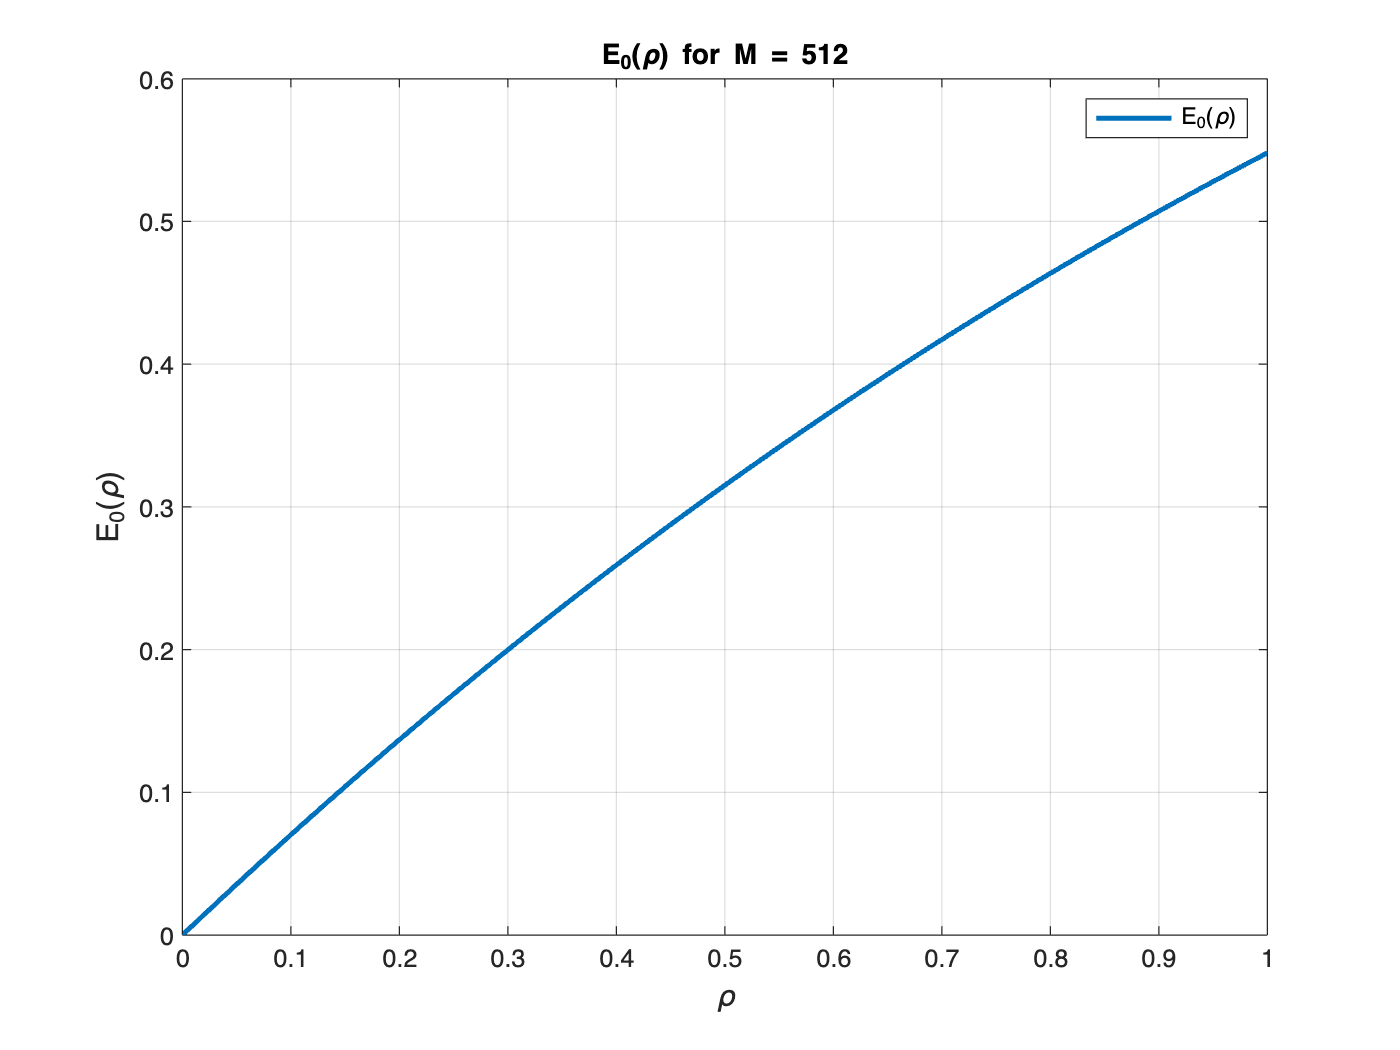


% Scaling behavior: Plot E0(ρ)
figure;
plot(rho_values, Eo_rho, 'LineWidth', 2, 'DisplayName', 'E_0(\rho)');
hold on;
xlabel('\rho', 'FontSize', 12);
ylabel('E_0(\rho)', 'FontSize', 12);
title('E_0(\rho) for M = 512');
grid on;
legend show;

## Using MATLAB Optimization Toolbox

clc; clear;

% Initialize parameters
N = 20;          % Number of quadrature nodes
SNR = 1;         % Signal-to-Noise Ratio
M = 2;          % Number of constellation points
d = 2;           % Distance parameter
R = 0.3;         % Transmission rate

% Compute Gauss-Hermite nodes and weights once
[nodes, weights] = GaussHermite_Locations_Weights(N);

% Generate and normalize PAM constellation
X = generatePAMConstellation(M, d);
X = X / sqrt(mean(X.^2));

% Initialize probability distribution
Q = repmat(1/M, 1, M);

% Define Gaussian function inline for better performance
G = @(z) exp(-abs(z).^2)/pi;

tic;
% Create matrices efficiently
pi_matrix = createPiMatrix(M, N, weights);
z_matrix = createComplexNodesMatrix(nodes);
g_matrix = createGMatrix(X, z_matrix, SNR, G);
matrix_time = round(toc*1000);

tic;
[optimal_rho, max_Eo] = optimizeRho_fminbnd(Q, pi_matrix, g_matrix, R);

 
 Func-count     x          f(x)         Procedure
    1       0.381966    -0.134225        initial
    2       0.618034    -0.191568        golden
    3       0.763932    -0.218099        golden
    4       0.854102    -0.231351        golden
    5        0.90983    -0.238403        golden
    6       0.944272    -0.242343        golden
    7       0.965558    -0.244621        golden
    8       0.978714     -0.24597        golden
    9       0.986844    -0.246782        golden
   10       0.991869    -0.247275        golden
   11       0.994975    -0.247576        golden
   12       0.996894    -0.247761        golden
   13       0.998081    -0.247875        golden
   14       0.998814    -0.247946        golden
   15       0.999267    -0.247989        golden
   16       0.999547    -0.248016        golden
   17        0.99972    -0.248032        golden
   18       0.999827    -0.248042        golden
   19       0.999893    -0.248049        golden
   20       0.999934    -0.248053  

optimal_rho =    0.999999478556584


max_neg_value =   -0.248058867170532


opt_time = round(toc*1000);

% Display results
fprintf('Matrix creation time: %d ms\n', matrix_time);

Matrix creation time: 33 ms


fprintf('Optimization time: %d ms\n', opt_time);

Optimization time: 47 ms


fprintf('Total execution time: %d ms\n', matrix_time + opt_time);

Total execution time: 80 ms


fprintf('Optimal rho: %.6f\n', optimal_rho);

Optimal rho: 0.999999


fprintf('Max value: %.6f\n', max_Eo);

Max value: 0.248059


## Newton's method optimization

clc; clear;

% System parameters
N = 20;          % Number of quadrature nodes
SNR = 1;         % Signal-to-Noise Ratio
M = 2;           % Constellation size
d = 2;           % Distance parameter
R = 0.5;         % Communication rate
tol = 1e-6;      % Convergence tolerance
max_iter = 100;  % Maximum iterations

% Compute Gauss-Hermite nodes and weights
[nodes, weights] = GaussHermite_Locations_Weights(N);

% Generate and normalize PAM constellation
X = generatePAMConstellation(M, d);
X = X / sqrt(mean(X.^2));  % Normalize to unit energy

% Initialize probability distribution (1×M)
Q = repmat(1/M, 1, M);
Q = Q';

% Define Gaussian function
G = @(z) exp(-abs(z).^2)/pi;

% Create matrices
tic;
pi_matrix = createPiMatrix(M, N, weights);
z_matrix = createComplexNodesMatrix(nodes);
g_matrix = createGMatrix(X, z_matrix, SNR, G);
matrix_time = toc;

fprintf('Matrix creation time: %.2f ms\n', matrix_time*1000);

Matrix creation time: 7.36 ms



% Perform Newton optimization
tic;
[rho_opt, Eo_max, iterations] = optimizationNewton(Q, pi_matrix, g_matrix, R, tol, max_iter)

gradient =   -2.983377357217497


curvatura =    5.797819626333967


   0.500000000000000



gradient =   -1.540843486099194


curvatura =    1.420131596351370


     1



ans =      5


rho_opt =      1


Eo_max =    0.048058916916968


iterations = uint32
   1


opt_time = toc;

% Display results
fprintf('\nOptimization Results:\n');


Optimization Results:


fprintf('Optimization time: %.2f ms\n', opt_time*1000);

Optimization time: 8.65 ms


fprintf('Total time: %.2f ms\n', (matrix_time + opt_time)*1000);

Total time: 16.01 ms


fprintf('Optimal rho: %.6f\n', rho_opt);

Optimal rho: 1.000000


fprintf('Maximum value: %.6f\n', Eo_max);

Maximum value: 0.048059


fprintf('Iterations: %d\n', iterations);

Iterations: 1


## fminsearch

 
 Iteration   Func-count         f(x)         Procedure
     0            1         0.684787         
     1            2         0.684787         initial simplex
     2            4         0.612335         expand
     3            6         0.469993         expand
     4            8         0.195942         expand
     5           10        -0.308224         expand
     6           12        -0.757985         reflect
     7           14        -0.757985         contract inside
     8           16        -0.966048         reflect
     9           18        -0.966048         contract inside
    10           20        -0.966048         contract inside
    11           22         -1.01631         reflect
    12           24         -1.01631         contract inside
    13           26         -1.01631         contract inside
    14           28         -1.02882         reflect
    15           30         -1.02882         contract inside
    16           32         -1.03508         refle

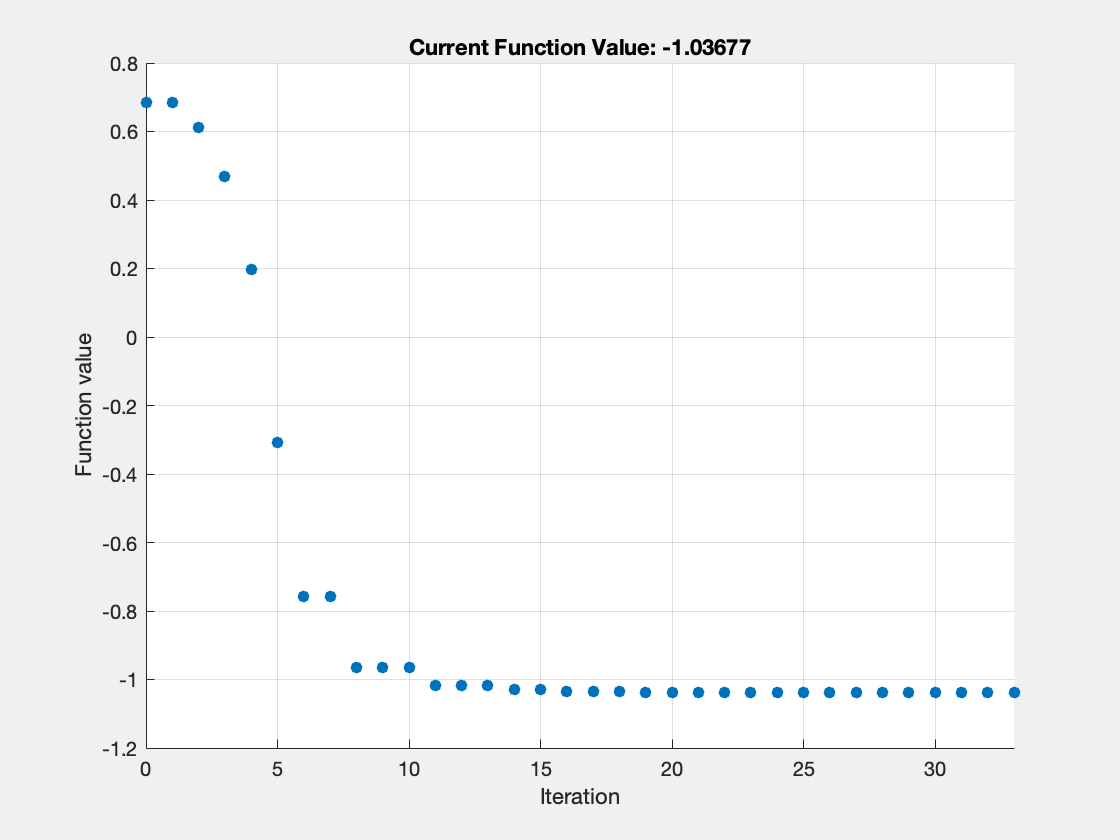

clc; clear;

% Initialize parameters
N = 20;          % Number of quadrature nodes
SNR = 1;         % Signal-to-Noise Ratio
M = 2;          % Number of constellation points
d = 2;           % Distance parameter
R = 2;         % Transmission rate

% Compute Gauss-Hermite nodes and weights once
[nodes, weights] = GaussHermite_Locations_Weights(N);

% Generate and normalize PAM constellation
X = generatePAMConstellation(M, d);
X = X / sqrt(mean(X.^2));

% Initialize probability distribution
Q = repmat(1/M, 1, M);

% Define Gaussian function inline for better performance
G = @(z) exp(-abs(z).^2)/pi;

tic;
% Create matrices efficiently
pi_matrix = createPiMatrix(M, N, weights);
z_matrix = createComplexNodesMatrix(nodes);
g_matrix = createGMatrix(X, z_matrix, SNR, G);
matrix_time = round(toc*1000);

tic;
[optimal_rho, max_Eo] = optimizeRho_fminsearch(Q, pi_matrix, g_matrix, R);

opt_time = round(toc*1000);

% Display results
fprintf('Matrix creation time: %d ms\n', matrix_time);

Matrix creation time: 13 ms


fprintf('Optimization time: %d ms\n', opt_time);

Optimization time: 424 ms


fprintf('Total execution time: %d ms\n', matrix_time + opt_time);

Total execution time: 437 ms


fprintf('Optimal rho: %.6f\n', optimal_rho);

Optimal rho: -0.920441


fprintf('Max value: %.6f\n', max_Eo);

Max value: 1.036768


[f, fp, f2p] = matricesDerivatives(Q, pi_matrix, g_matrix, 1);
% Optimize divisions by precomputing repeated values
f_inv = 1/f;
fp_f = fp * f_inv;
log2_const = log(2);  % Precompute constant

% Compute gradient and curvature with minimized operations
gradient = -fp_f / log2_const - R

gradient =   -1.604598659103928


curvatura = -((f2p * f_inv) - fp_f * fp_f) / log2_const

curvatura =   -0.448222253662552
